# Applied Mathematics

## Numerical Optimization

### Function derivatives

Jacobian, gradient and Hessian:

- Scalar-valued function: $\frac{\partial }{\partial x}f\left(x\right)$, $\nabla f\left(x\right)=\frac{\partial }{\partial x}{f\left(x\right)}^T$, $[\nabla f^2(x)]_{ij}=\frac{\partial f^2}{\partial x_i \partial x_j}(x)$

- Vector-valued function: ${\left\lbrack \frac{\partial }{\partial x}F\left(x\right)\right\rbrack }_{\textrm{ij}} =\frac{\partial }{\partial x_j }F_i \left(x\right)$, $\nabla F={\left(\frac{\partial }{\partial x}F\left(x\right)\right)}^T$, $[\nabla^2F(x)]_{ijk}=\frac{\partial F^2_i}{\partial x_j\partial x_k}(x)$

### Problem Definition

#### **general optimization problem**


$${\textrm{minimize}}_{x\in R^{n_v } } \;f\left(x\right)$$



$$\begin{array}{l}
\textrm{subject}\;\textrm{to}\;\textrm{Ax}\le b\\
A_{\textrm{eq}} x{=b}_{\textrm{eq}} \\
c\left(x\right)\le 0\\
c_{\textrm{eq}} \left(x\right)=0\\
l\le x\le u\;
\end{array}$$


- $l,u\in R^{n_v }$ are box constraints

- $c:R^{n_v } \to R^{n_{\textrm{ineq}}^{\textrm{nl}} }$ are nonlinear inequality constraints

- $c_{\textrm{eq}} :R^{n_v } \to R^{n_{\textrm{eq}}^{\textrm{nl}} }$ are nonlinear equality constraints

- $A\in R^{n_{\textrm{ineq}}^{\textrm{lin}} \times n_v }$ define linear inequality constraints

- $A_{\textrm{eq}} \in R^{n_{\textrm{eq}}^{\textrm{lin}} \times n_v }$ define linear equality constraints

#### **Lagrangian and Karush-Kuhn-Tucker (KKT) optimality conditions**


$${\textrm{minimize}}_{x\in R^{n_v } } \;f\left(x\right)$$



$$\begin{array}{l}
\mathrm{subject}\;\mathrm{to}\;g\left(x\right)\le 0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;h\left(x\right)=0
\end{array}$$


Lagrangian: $L(x,\lambda,\mu)=f(x)+\lambda^Tg(x)+\mu^Th(x)$

KKT conditions to test for optimality 

    
$$\nabla_x L(x^*,\lambda^*,\mu^*)=0\\
g(x^*)\le0\\
h(x^*)=0\\
\lambda^*\ge0\\
{\lambda^*}^Tg(x^*)=0$$


### Nonlinear System of Equations

Find $x\in R^n$ such that


$$F\left(x\right)=0$$


where $F:R^n \to R^m$ is continuously differentiable, nonlinear function.

- Solution methods are iterative, in general, which require initial guess and convergence criteria

- Solution is not guaranteed to exist

- If the solution, it is not necessarily unique. The solution found depends heavily on the initial guess

addpath('demo/')

#### $n=m=1$ case

**Derivative-free methods**

- Only require evaluations of f(x)

- Bisection, Fixed point iteration, etc.

`EX. bisection_demo.m`

bisection_demo(@(x) sin(x),[-1.5*pi,1.25*pi]);

**Gradient-based methods**

- Requires function, f(x), and gradient, f'(x), evaluations

- Newton's method: $x_{k+1}=x_k-\frac{f(x_k)}{f'(x_k)}$

- Secant method: use finite differences to approximate gradients instead of analytic gradients (only requires function evaluations)

`EX. newton_demo.m`

% Should work easily
newton_demo(@(x) x.^2-1,@(x) 2*x,5,[-6,6]);

% Should work, but not easily (gradient -> 0 at solution)
newton_demo(@(x) x.^2,@(x) 2*x,5,[-6,6]);

% Might work, but unpredictable, start near extrema
newton_demo(@(x) sin(x),@(x) cos(x),3*pi/2-0.1,[-10*pi,10*pi]);

`fzero` (for scalar functions)

- Derivative-free

- Combines bisection, secant, and interpolation methods

- `[x,fval,exitflag,output] = fzero(fun,x0,options)`

- a MATLAB builtin command for finding a root of a continuous, scalar-valued, univariate function

Ex.

[x1,fval1,exitflag1,output1] = fzero(@(x) x^2-1,4);

**Quiz. **

Try solving $x^2=0$ and $x^2+1=0$ using `fzero`. What do you get? How would you explain the results?

[x2,fval2,exitflag2,output2] = fzero(@(x) x^2,4);
[x3,fval3,exitflag3,output3] = fzero(@(x) x^2+1,4);

#### general case

**Derivative-free methods**

- Requires function, F(x), evaluations

- Fixed point iteration, Secant method, etc

**Gradient-based methods**

- Requires function and Jacobian evaluations

- Newton-Raphson method

- Gauss-Newton and Levenberg-Marquardt (nonlinear least squares: $\min \;\left|\right|F\left(x\right)\left|\right|$)

- Can use finite difference approximations to gradients instead of analytic gradients (only requires function evaluations)

`fsolve `(for vector-valued functions)

- Gradient-based

- `[x,fval,exitflag,output,jac] = fsolve(fun,x0,options)`

- Algorithms: standard trust region (default), trust region reflexive, Gauss-Newton, Levenberg-Marquardt

- By default uses finite differences to compute Jacobian; To supply analytic Jacobian, `fun` return Jacobian as second output and `options.Jacobian = 'on'`

Ex.

x0 = [1;1];
% without Jacobian information
[x1,f1,exit1,out1] = fsolve(@fsolve_func,x0);

% with Jacobian information
options = optimset('Jacobian','on');
[x2,f2,exit2,out2] = fsolve(@fsolve_func,x0,options);

% number of function evaluations
out1.funcCount
out2.funcCount

### Types of Optimization Solvers

**Derivative-free**

Only function evaluations used

- Brute force

- Genetic algorithms

- Finite difference computations of gradients/Hessians

Usually require very large number of function evaluations

**Gradient-based**

Most popular class of techniques

Function and gradient evaluations used

- Finite difference computations of Hessians

- SPD updates to build Hessian approximations (BFGS)

**Hessian-based**

Hessians is usually difficult/expensive to compute, although often very sparse

Second-order optimality conditions

Function, gradient, and Hessian evaluations used

**Interior point methods**

Iterates always strictly feasible

Use barrier functions to keep iterates away from boundaries

Sequence of optimization problems

**Active set methods**

Active set refers to the inequality constraints active at the solution

Possibly infeasible iterates when constraints nonlinear

Minimize problem for given active set, then update active set based on Lagrange multipliers

**Globalization**: techniques to make optimization solver globally convergent (convergent to some local minima from any starting point)

- Trust region methods

- Line search methods

#### Linear Program (LP)


$${\textrm{minimize}}_{x\in R^{n_v } } \;f^T x$$



$$\begin{array}{l}
\textrm{subject}\;\textrm{to}\;\textrm{Ax}\le b\\
A_{\textrm{eq}} x{=b}_{\textrm{eq}} \\
l\le x\le u\;
\end{array}$$


**MATLAB solver (**`linprog`**)**

Medium-scale

- Simplex method

- `options = optimset('LargeScale', 'off', 'Simplex', 'on')`

Large-scale

- Primal-dual interior point method

- Default

**Demo**

Find the optimal combination of food that provides desired nutrients while minimizing the cost.

% Nutrients: [calories; protein; fiber; vitamin C]
% Food:      [subway tuna footlong, banana, egg, PB ]

cost = [6.5;1.0;0.25;0.10];
nutrients = [960,120,71,188;... % calories for each food
             40,1,6,8;... % protein for each food
             10,4,0,0;... % fiber for each food
             40,20,0,0]; % vitamin C for each food

f = cost;
A = [-nutrients;nutrients];
b = [ -[100;40;10;100] ; [2000;1000;1000;10000] ];
lower = [1;0;0;0];
upper = [inf;inf;inf;inf];

[x,fval,exitflag]=linprog(f,A,b,[],[],lower,upper)

**Binary integer linear program**

- x is a binary number, either 0 or 1

- NP-hard

- `bintprogram`

- `intlinprog: m`ixed-integer linear programming solver

#### Quadratic Program (QP)


$${\textrm{minimize}}_{x\in R^{n_v } } \;{\frac{1}{2}x^T \textrm{Hx}+f}^T x$$



$$\begin{array}{l}
\mathrm{subject}\;\mathrm{to}\;\;\;\;\mathrm{Ax}\;\le \;b\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;A_{\mathrm{eq}} x{\;=\;b}_{\mathrm{eq}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;l\le x\le u\;
\end{array}$$


**MATLAB solver (**`quadprog`**)**

Medium-scale

- Active-set method with linear subproblems

Large-scale

- Trust region reflexive method: Newton-type method, Preconditioned CG to solve linear system

#### Unconstrained Optimization


$${\textrm{minimize}}_{x\in R^{n_v } } \;f\left(x\right)$$


**MATLAB solvers**

`fminsearch`: Derivative-free, Simplex search

`fminunc`: Quasi-Newton with linesearch (medium scale), Trust region reflexive (large scale)

#### Linearly Constrained Optimization


$${\textrm{minimize}}_{x\in R^{n_v } } \;f\left(x\right)$$



$$\begin{array}{l}
\mathrm{subject}\;\mathrm{to}\;\mathrm{Ax}\le b\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\;A}_{\mathrm{eq}} x{=b}_{\mathrm{eq}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;l\le x\le u\;
\end{array}$$


Or only the box constraints.

**MATLAB solvers**

`fminbnd`: Single variable optimization

`fmincon`: Trust region reflexive method, Active-set method

#### Nonlinear Constraints

Solvers

- Trust region reflexive

- Sequential Quadratic Programming (SQP)

- Interior Point (IP)

#### Syntax for call to Optimization Toolbox

`[x,fval,exitflag,out,lam,grad,hess] = ...`

`solver(f,x0,A,b,Aeq,beq,lb,ub,nlcon,opt)`

`[x,fval,exitflag,out,lam,grad,hess] = solver(problem)`

**Inputs**

- `f - `function handle (or vector for LP) defining objective function (and gradient)

- `x0 - `vector defining initial guess

- `A,b - `matrix, RHS defining linear inequality constraints

- `Aeq, beq - `matrix, RHS defining linear equality constraints

- `lb,ub -` vectors defining lower, upper bounds

- `nlcon -` function handle defining nonlinear contraints (and Jacobians)

- `opt -` optimization options structure

- `problem -` structure containing above information

**Outputs**

- `x - `minimum found

- `fval - `value of objective function at x

- `exitflag - `describes exit condition of solver

- `out - `structure containing output information

- `lam - `structure containing Lagrange multipliers at x

- `grad - `gradient of objective function at x

- `hess - `Hessian of objective function at x

Instead of specifying many different inputs in a call to the optimizer, store inputs in `problem`** structure** with fields `objective, x0, Aineq, bineq, Aeq, beq, lb, ub, nonlcon, solver, options.`

Each optimization solver has tunable options that can be specified with an `options`** structure.**

- `optimset <solver> `to return options available for particular solver, along with default values

#### Demo

Consider the following *nonlinearly constrained* optimization problem:

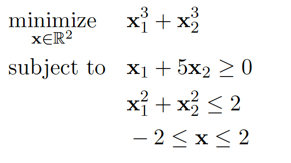

- Derive derivative information for objective and nonlinear constraints.

- Convert optimization problem into MATLAB compatible form.

- Solve using `fmincon.`

addpath([pwd,'/demo'])
x0 = [1;1];
A  = [-1,-5];
b  = 0;
lb = [-2;-2];
ub = [2;2];

% turn on: 
%   user-defined gradients for the nonlinear constraints
%   user-defined gradients for the objective functions
%   display of output at each iteration
options = optimset('GradConstr','on', 'GradObj','on', 'Display', 'iter');
[xstar,fstar exitflag output] = fmincon(@fmincon_obj,x0,A,b,[],[],lb,ub,@fmincon_constr, options);

[X,Y] = meshgrid(linspace(lb(1),ub(1),30),linspace(lb(2),ub(2),30));
F = zeros(size(X));
C = zeros(size(X));
AA = zeros(size(X));

for i = 1:size(X,1)
    for j = 1:size(X,2)
        F(i,j) = fmincon_obj([X(i,j),Y(i,j)]);
        C(i,j) = fmincon_constr([X(i,j),Y(i,j)]);
        AA(i,j)= A*[X(i,j);Y(i,j)];
    end
end

% plot the objective function
figure;
h(1) = surf(X,Y,F);
xlabel('x1'); ylabel('x2');
view(gca,[-81.5 48]);

% plot the constraints
figure;
h(2) = surf(X,Y,C,'edgecolor','r'); hold on;
h(3) = surf(X,Y,AA,'edgecolor','b');
h(4) = surf(X,Y,0*F,'edgecolor','none','facecolor','k');
xlabel('x1'); ylabel('x2');
view(gca,[-105.5 21.0]);

figure;
h(5) = surf(X,Y,F); hold on;
h(6) = surf(X,Y,C,'edgecolor','none','facecolor','r','facealpha',0.5);
h(7) = surf(X,Y,AA,'edgecolor','none','facecolor','b','facealpha',0.5);
h(8) = surf(X,Y,0*F,'edgecolor','none','facecolor','k','facealpha',0.5);
h(9) = plot3(xstar(1),xstar(2),fstar,'co','markersize',12,...
    'markerfacecolor','c','markeredgecolor','w');
h(10) = plot3(xstar(1),xstar(2),0,'mo','markersize',8,...
    'markerfacecolor','m','markeredgecolor','k');
xlabel('x1'); ylabel('x2');
view(gca,[-105.5 21.0]);
legend("objective","nonlinear constraint","linear constraint",...
"zero plane","optimal solution","0 at solution point")

### Optimization Toolbox GUI (`optimtool`)

MATLAB's Optimization Toolbox comes equipped with GUI

- `optimtool` to launch

- User-friendly

- Import `problem` or options from workspace

- Generate code

- Export optimization problem to workspace

optimtool

*- removed in a future release. *

**Alternative: **

Optimize Live Editor Task (introduced in R2020b): Interactively create and solve optimization problems with MATLAB, Optimization Toolbox, or Global Optimization Toolbox using a visual interface. See [https://www.mathworks.com/videos/how-to-use-the-optimize-live-editor-task-1594660384855.html](https://www.mathworks.com/videos/how-to-use-the-optimize-live-editor-task-1594660384855.html) for an introduction video.

**Parallel Computations** available with commands `fmincon, fminattain, fminimax`

Start MATLAB pool of workers

Set `UseParallel` option to 'always'

`parfor` to loop over multiple initial conditions

- Attempt at global optimization

- Embarrassingly parallel

clear; clc

## Symbolic Math

### Symbolic computations in MATLAB

Symbolic variables, expressions, functions

% Symbolic variables
syms u v

% Symbolic expression
phi1 = str2sym('(1+sqrt(5))/2') % golden ratio
phi2 = str2sym('(1-sqrt(5))/2') 

phi1*phi2 

simplify(phi1*phi2)

% Symbolic function
syms f(u,v)
f(u,v) = u^2*v

f(3,2)

Symbolic matrices can be constructed from symbolic variables

syms a b c d
A = [a^2, b, c; d*b,c-a,sqrt(b)]

b = [a;b;c];
A*b

Arithmetic, Relational, and Logical Operations

- Symbolic arithmetic operations: `ceil, cong, cumprod, cumsum, fix, floor, frac, imag, minus, mod, plus, quorem, real, round`

- Symbolic relational operations: `eq, ge, gt, le, lt, ne, isequaln`

- Symbolic logical operations: `and, not, or, xor, all, any, isequaln, isfinite, isinf, isnan, logical`

#### Commands

**Equation Solving**

- `finverse` Functional inverse

- `linsolve` Solve linear system of equations

- `poles` Poles of expression/function

- `solve` Equation/System of equations solver

- `dsolve` ODE solver

**Formula Manipulation and Simplification**

- `simplify` Algebraic simplification

- `simplifyFraction` Symbolic simplification of fractions

- `subexpr` Rewrite symbolic expression in terms of common subexpression

- `subs` Symbolic substitution

subs(A*b,c,4)
subs(A*b,{a,c},{sym('alpha'),4})

**Demo.**

Consider this famous equation that explains relationship between energy ($E$), rest mass ($m_0
$), speed of light ($c$), and velocity ($v$) of an object under motion:


$$E = \frac{m_0c^2}{\sqrt{1-v^2/c^2}}$$


Find the positive velocity as a function of other variables using MATLAB. Type in the exact format that appears in MATLAB. 

syms E m_0 c v positive;
solve(E == m_0 * c^2/sqrt(1-v^2/c^2), v) 

**Calculus**

- `diff` Differentiate symbolic

- `int` Deffnite and indefinite integrals

- `rsums` Riemann sums

- `curl` Curl of vector field

- `divergence` Divergence of vector field

- `gradient` Gradient vector of scalar function

- `hessian` Hessian matrix of scalar function

- `jacobian` Jacobian matrix

- `laplacian` Laplacian of scalar function

- `potential` Potential of vector field

- `vectorPotential` Vector potential of vector field

- `taylor` Taylor series expansion

- `limit` Compute limit of symbolic expression

- `fourier` Fourier transform

- `ifourier` Inverse Fourier transform

- `ilaplace` Inverse Laplace transform

- `iztrans` Inverse Z-transform

- `laplace` Laplace transform

- `ztrans` Z-transform

**Linear Algebra**

Most matrix operations available for numeric arrays also available for symbolic matrices.

- `adjoint` Adjoint of symbolic square matrix

- `expm` Matrix exponential

- `sqrtm` Matrix square root

- `cond` Condition number of symbolic matrix

- `det` Compute determinant of symbolic matrix

- `norm` Norm of matrix or vector

- `colspace` Column space of matrix

- `null` Form basis for null space of matrix

- `rank` Compute rank of symbolic matrix

- `rref` Compute reduced row echelon form

- `eig` Symbolic eigenvalue decomposition

- `jordan` Jordan form of symbolic matrix

- `chol` Symbolic Cholesky decomposition

- `lu` Symbolic LU decomposition

- `qr` Symbolic QR decomposition

- `svd` Symbolic singular value decomposition

- `inv` Compute symbolic matrix inverse

- `linsolve` Solve linear system of equations

**Assumptions**

- `assume` Set assumption on symbolic object

- `assumeAlso` Add assumption on symbolic object 

- `assumptions` Show assumptions set on symbolic variable

assume(c>0)
assumptions

**Polynomials**

- `charpoly` Characteristic polynomial of matrix

- `coeffs` Coeffcients of polynomial

- `minpoly` Minimal polynomial of matrix

- `poly2sm` Symbolic polynomial from coeffcients

- `sym2poly` Symbolic polynomial to numeric

**Mathematical Functions**

- `log, log10, log2` Logarithmic functions

- `sin, cos tan`, etc Trigonometric functions

- `sinh, cosh tanh`, etc Hyperbolic functions

Complex numbers and operations also available

**Precision Control**

- `digits` Variable-precision accuracy

- `double` Convert symbolic expression to MATLAB double

- `vpa` Variable precision arithmetic

phi = (1+sqrt(sym(5)))/2
vpa(phi,6)

#### **Code generation**

`ccode` C code representation of symbolic expression

`fortran` Fortran representation of symbolic expression

`latex` LATEX representation of symbolic expression

`matlabFunction `Convert symbolic expression to function handle or file

`texlabel `TeX representation of symbolic expression

latex(phi)

close all; clear; clc

## ODE and PDE

### ODE

A system of **Ordinary Differential Equations (ODEs)** can be written in the form


$$\frac{dy}{dt}(t)=F(t,y)$$



$$y(0)=y_0$$


An ODE problem is **stiff** if the solution being sought is varying slowly, but there are nearby solutions that vary rapidly, so a numerical method must take small steps to obtain satisfactory results. Numerical schemes applied to stiff problems have very restrictive time steps for stability

**Various types of ODE solvers**

- Multi- vs single-stage

- Multi- vs single-step (Number of time steps used approximate time derivative)

- Implicit vs. Explicit (Trade-off between ease of advancing a single step versus number of steps required. Implicit schemes usually require solving a system of equations.)

- Serial vs. Parallel

#### Fourth-Order Explicit Runge-Kutta (ERK4)

A multi-stage, single-step, explicit, serial ODE solver.

Discretization of the time domain into $N+1$ intervals.

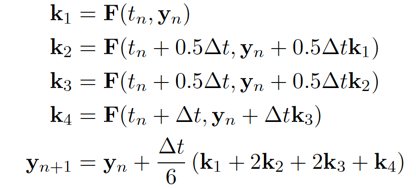

Fourth-order accuracy: error $\mathcal{O}(\Delta t^4)$

#### MATLAB ODE Solvers

`[TOUT,YOUT] = ode_solver(ODEFUN,TSPAN,Y0)`

`ODEFUN `is a function handle. 

- For a scalar T and a vector Y, `ODEFUN(T,Y) `must return a column vector corresponding to f(t,y)

`TSPAN = [T0 TFINAL]`

`Y0 `is the initial conditions 

Each row in the solution array `YOUT` corresponds to a time returned in the column vector `TOUT.`

Some options for `ode_solver`, its stiffness and accuracy:

- `ode45` Nonstiff, Medium

- `ode23` Nonstiff, Low

- `ode113` Nonstiff, Low - High

- `ode15s` Stiff, Low - Medium

- `ode23s` Stiff, Low

- `ode23t` Moderately stiff, Low

- `ode23tb` Stiff, Low

**Demo**

Solve the simplified combustion model 

$y\prime \left(t\right)=y^2 \left(1-y\right)$, $0\le t\le \frac{2}{\epsilon },y\left(0\right)=\epsilon$ 

using `ode45` and `ode23s` with $\epsilon ={10}^{-4} ,{10}^{-3} ,{10}^{-2} ,{10}^{-1} ,1$.

% ODE solvers
eps = [1, 1e-1 1e-2 1e-3 1e-4];
%eps = 1e-4;
f = @(t,y) y^2*(1-y);
for i = 1:length(eps)
    [t45,y45]  = ode45(f,[0,2/eps(i)],eps(i));
    [t23s,y23s] = ode23s(f,[0,2/eps(i)],eps(i));
    fprintf('ODE45 Timesteps for eps = %f: %d\n', eps(i),length(t45))
    fprintf('ODE23s Timesteps for eps = %f: %d\n', eps(i),length(t23s))
    if (eps(i) == 1e-1)
        plot(t45,y45,'b-', t23s, y23s, 'r--');
        legend('ODE45', 'ODE23')
    end
end

### PDE (partial differential equation)

The function being solved for depends on several variables, and the differential equation can include partial derivatives taken with respect to each of the variables.

Partial Differential Equations are ubiquitous in science and engineering. Some examples are

- Fluid Mechanics: Euler equations, Navier-Stokes equations

- Solid Mechanics: Structural dynamics

- Electrodynamics: Maxwell equations

- Quantum Mechanics: Schrodinger equation

Analytical solutions over arbitrary domains are mostly unavailable.

#### Classification of PDEs

**hyperbolic**:

- Ex: wave equation $\frac{\partial^2 u}{\partial t^2} -c^2 \frac{\partial^2 u}{\partial x^2}=0$

- Hyperbolic equations model the transport of some physical quantity, such as fluids or waves. 

**parabolic**:

- Ex: heat equation $\frac{\partial u}{\partial t} = \frac{\partial^2 u}{\partial x^2}$

- Parabolic problems describe evolutionary phenomena that lead to a steady state described by an elliptic equation. 

**elliptic**:

- Equations without a time derivative. 

- Ex: Laplace equation $\frac{\partial^2 u}{\partial x^2}=0$

- Elliptic equations are associated to a special state of a system, in principle corresponding to the minimum of the energy.

#### **Numerical Methods for solving PDEs**

- Finite Difference (FD)

- Finite Element (FE)

- Finite Volume (FV)

- Spectral (Fourier, Chebyshev)

- Discontinuous Galerkin (DG)

The (major) steps required to compute the numerical solution of to a system of Partial Differential Equations are

- Derive discretization of governing equations (Semi-discretization; Space-time discretization; Boundary conditions)

- Construct spatial mesh (or space-time mesh)

- If semi-discretized, define temporal mesh

- Implement and solve

- Postprocess

#### 1-D PDE solver in MATLAB

$u(x,t)$ that depends on time *t* and one spatial variable x

`sol = ``pdepe``(m,pdefun,icfun,bcfun,xmesh,tspan) `solves 1-D parabolic and elliptic PDEs

- `m` is the symmetry constant.

- `pdefun` defines the equations being solved.

- `icfun` defines the initial conditions.

- `bcfun` defines the boundary conditions.

- `xmesh` is a vector of spatial values for *x*.

- `tspan` is a vector of time values for *t*.

- `sol` is a 3-D solution array. `ui` = `sol`(`:`,`:`,`i`) is an approximation to the `i`th component of the solution vector $u$. The element `ui`(`j`,`k`) = `sol`(`j`,`k`,`i`) approximates $u_i$ at (*t*,*x*) = (`tspan`(`j`),`xmesh`(`k`)).

The **standard form** that `pdepe` expects is


$$c\left(x,t,u,\frac{\partial u}{\partial x}\right)\frac{\partial u}{\partial t}=x-m\frac{\partial }{\partial x}\left(x^m f\left(x,t,u,\frac{\partial u}{\partial x}\right)\right)+s\left(x,t,u,\frac{\partial u}{\partial x}\right)$$


The initial condition function should have signature `u0 = pde_ic(x).` 

The standard form for the boundary conditions expected by the solver is


$$p\left(x,t,u\right)+q\left(x,t\right)f\left(x,t,u,\frac{\partial u}{\partial x}\right)=0$$


and use the function signature `[pl,ql,pr,qr] = pde_bc(xl,ul,xr,ur,t).`

**Demo**:  solve $\pi^2\frac{\partial u}{\partial t} = \frac{\partial^2 u}{\partial x^2}$ with initial condition $u(x,0)=\sin(\pi x)$ and boundary conditions $u(0,t)=0, \pi e^{-t}+\frac{\partial u}{\partial x}(1,t)=0$.

- code the equation: $\pi^2 \frac{\partial u}{\partial t}=x^0 \frac{\partial }{\partial x}\left(x^0 \frac{\partial u}{\partial x}\right)+0$ 

- code the initial conditions 

- code the boundary conditions: $u+0\cdot \frac{\partial u}{\partial x}=0,\pi e^{-t} +1\cdot \frac{\partial u}{\partial x}\left(1,t\right)=0$ 

- select a suitable solution mesh 

- call the solver `pdepe`

`pde1d_demo.m`

Example of solving a system of PDEs: [https://www.mathworks.com/help/matlab/math/solve-system-of-pdes.html](https://www.mathworks.com/help/matlab/math/solve-system-of-pdes.html) 

#### Partial Differential Equation Toolbox for General PDEs

A typical workflow for solving a general PDE or a system of PDEs includes the following steps:

- Convert PDEs to the form required by the toolbox.

- Create a PDE model container specifying the number of equations.

- Define 2-D or 3-D geometry and mesh it using triangular and tetrahedral elements with linear or quadratic basis functions.

- Specify the coefficients, boundary and initial conditions. 

- Solve and plot the results at nodal locations or interpolate them to custom locations.

**Geometry Definition**

Construct mesh interactively using pdetool

- Unions and intersections of basic shapes: Rectangles, ellipses, circles, etc

Use `pdegeom` to create geometry programmatically

- Build parametrized, oriented boundary edges

- Label left and right regions of edges

- Geometry built from union of regions with similar labels

**Mesh Generation**

- `initmesh` Create initial triangular mesh

- `adaptmesh `Adaptive mesh generation and PDE solution

- `jigglemesh` Jiggle internal points of triangular mesh

- `reinemesh` Refine triangular mesh

- `tri2grid `Interpolate from PDE triangular mesh to rectangular grid

- `pdemesh` Plot PDE triangular mesh

- `pdetriq` Triangle quality measure

**Demo**

The NACA airfoils are airfoil shapes for aircraft wings developed by the National Advisory Committee for Aeronautics (NACA).

[p,e,t]=initmesh('naca');
pdemesh(p,e,t), axis equal

**Problem Definition**

Both scalar and vector PDEs are available in PDE toolbox.

Here we focus on **scalar PDEs**.

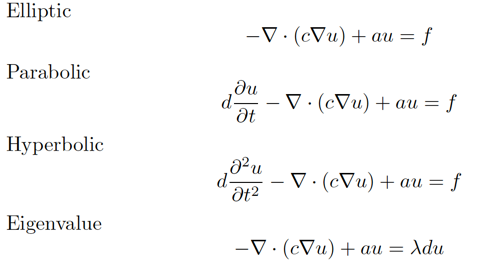

PDE coefficients $a,c,d,f$ can vary with space and time (can also depend on the solution $u$ or the edge segment index)

**Boundary conditions** are available for both scalar and vector available in PDE toolbox.

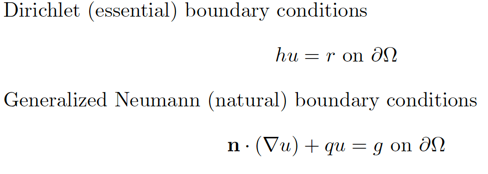

Boundary coefficients $h,r,q,g$ can vary with space and time (can also depend on the solution $u$ or the edge segment index)

**Specify Boundary Conditions**

Boundary conditions can be specified:

- Graphically using `pdetool`

- Programmatically using `pdebound: [q,g,h,r] = pdebound(p,e,u,time)`

**Specify PDE Coeffcients**

PDE coeffcients can be specified:

- Graphically using `pdetool`

- Programmatically via constants, strings, functions: `u = parabolic(u0,tlist,b,p,e,t,c,a,f,d);`

**PDE solvers**

- Elliptic: `[u,res]=pdenonlin(b,p,e,t,c,a,f);`

- Parabolic: `u=parabolic(u0,tlist,b,p,e,t,c,a,f,d);`

- Hyperbolic: `u=hyperbolic(u0,ut0,tlist,b,p,e,t,c,a,f,d);`

`result = ``solvepde``(model``) `solves a stationary PDE defined by the PDEModel `model` and returns the `result` in a StationaryResults object.

**Demo**

u=parabolic(0,linspace(0,0.1,200),@nacabound,p,e,t,1,0,0,1);
pdeplot(p,e,t,'xydata',u(:,end),'colormap','jet'); axis equal;